% load the test data
% Row1 - left wheel angular velocity (rad/s) limits (0-6.2 rad/s)
% Row2 - right wheel angular velocity
% Row3 - linear velocity of body (m/s)
% Row4 - angular velocity of body (rad/s)
data = load("C:\Users\pala\OneDrive - Clemson University\PhD Research\DECLab\Ameya_IMM\Data\datsSet.mat");

%%% Input to the filter framework
Input1 = data.dataSet(1).data(1:2,:); % wheel angular velocities from first data set
Input2 = data.dataSet(2).data(1:2,:);
Input3 = data.dataSet(3).data(1:2,:);
Input4 = data.dataSet(4).data(1:2,:);
Input5 = data.dataSet(5).data(1:2,:);
Input6 = data.dataSet(6).data(1:2,:);
Input7 = data.dataSet(7).data(1:2,:);
Input8 = data.dataSet(8).data(1:2,:);

U = Input(Input1);
dt = 0.1 ;
t = 0:dt:(length(Input1(1,:))-1)*dt;
t2 = t(1:end-1); % for Input 3, Input 5 and Input 7

%%% Output to the filter framework -->Ground truth data
Output1 = data.dataSet(1).data(3:4,:); % linear velocities and angular velocities from first data set
Output2 = data.dataSet(2).data(3:4,:);
Output3 = data.dataSet(3).data(3:4,:);
Output4 = data.dataSet(4).data(3:4,:);
Output5 = data.dataSet(5).data(3:4,:);
Output6 = data.dataSet(6).data(3:4,:);
Output7 = data.dataSet(7).data(3:4,:);
Output8 = data.dataSet(8).data(3:4,:);

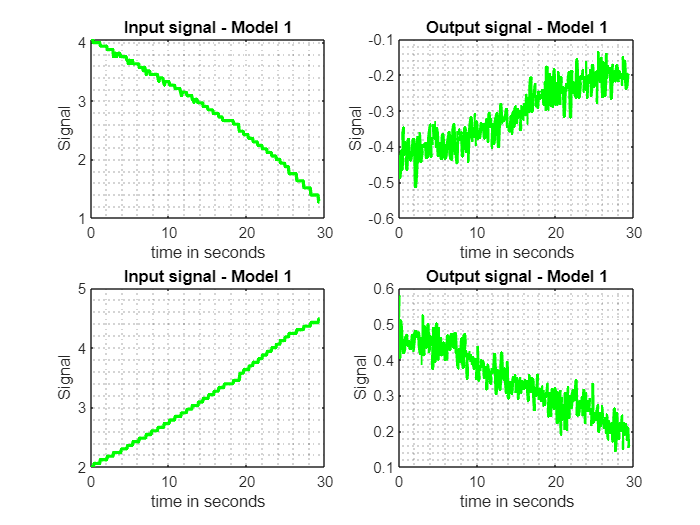


%% Plots of the input and output
figure(1)
subplot(2,2,1)
plot(t,U(1,:),'LineWidth',2)
plot(t,U(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 1')
grid minor
subplot(2,2,2)
plot(t,Output1(1,:),'LineWidth',2)
plot(t,Output1(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 1')
grid minor
subplot(2,2,3)
plot(t,Input2(1,:),'LineWidth',2)
plot(t,Input2(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 1')
grid minor
subplot(2,2,4)
plot(t,Output2(1,:),'LineWidth',2)
plot(t,Output2(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 1')
grid minor

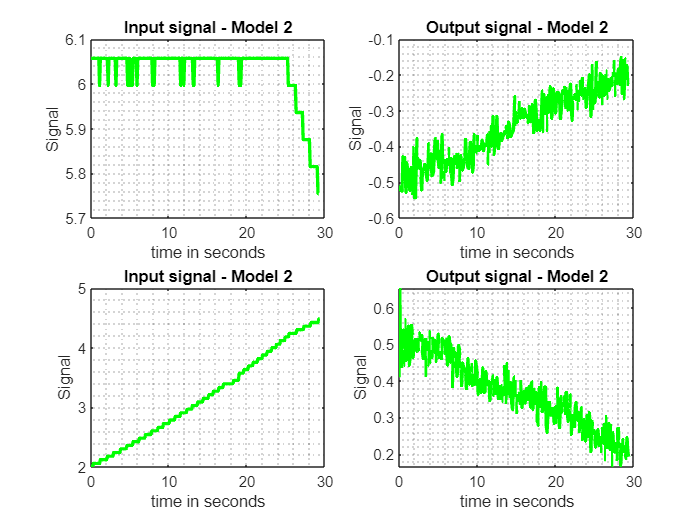


figure(2)
subplot(2,2,1)
plot(t2,Input3(1,:),'LineWidth',2)
plot(t2,Input3(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 2')
grid minor
subplot(2,2,2)
plot(t2,Output3(1,:),'LineWidth',2)
plot(t2,Output3(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 2')
grid minor
subplot(2,2,3)
plot(t,Input4(1,:),'LineWidth',2)
plot(t,Input4(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 2')
grid minor
subplot(2,2,4)
plot(t,Output4(1,:),'LineWidth',2)
plot(t,Output4(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 2')
grid minor

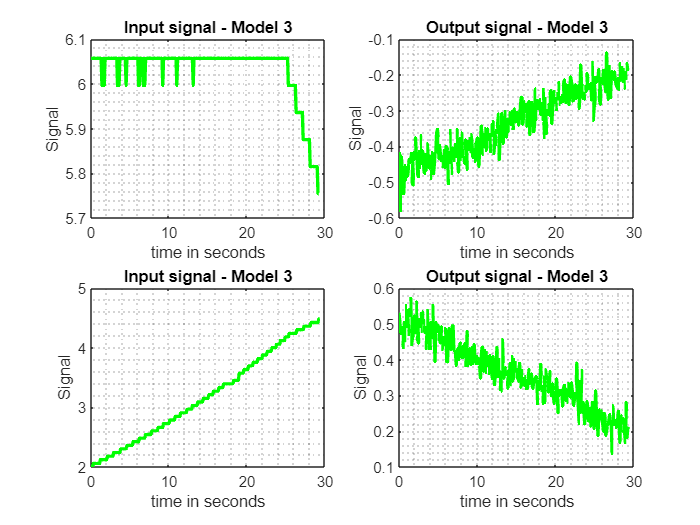


figure(3)
subplot(2,2,1)
plot(t2,Input5(1,:),'LineWidth',2)
plot(t2,Input5(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 3')
grid minor
subplot(2,2,2)
plot(t2,Output5(1,:),'LineWidth',2)
plot(t2,Output5(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 3')
grid minor
subplot(2,2,3)
plot(t,Input6(1,:),'LineWidth',2)
plot(t,Input6(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 3')
grid minor
subplot(2,2,4)
plot(t,Output6(1,:),'LineWidth',2)
plot(t,Output6(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 3')
grid minor

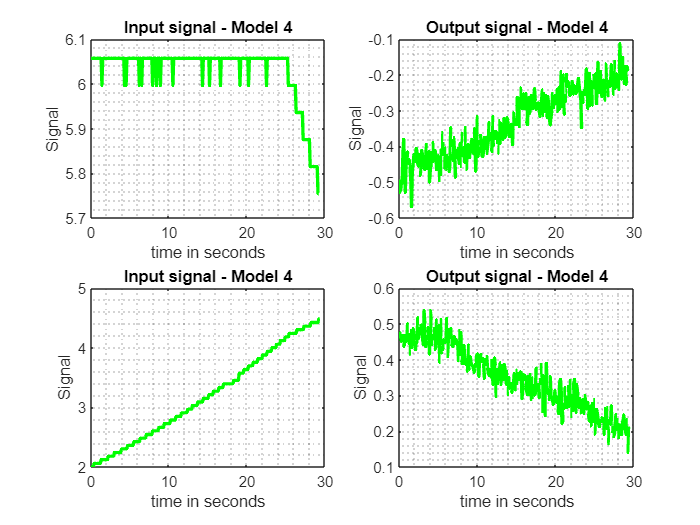


figure(4)
subplot(2,2,1)
plot(t2,Input7(1,:),'LineWidth',2)
plot(t2,Input7(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 4')
grid minor
subplot(2,2,2)
plot(t2,Output7(1,:),'LineWidth',2)
plot(t2,Output7(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 4')
grid minor
subplot(2,2,3)
plot(t,Input8(1,:),'LineWidth',2)
plot(t,Input8(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Input signal - Model 4')
grid minor
subplot(2,2,4)
plot(t,Output8(1,:),'LineWidth',2)
plot(t,Output8(2,:),'LineWidth',2,'Color','g')
xlabel('time in seconds')
ylabel('Signal')
title('Output signal - Model 4')
grid minor

function U = Input(X)
V_com = sum(X);
W_com = diff(X);
U = [V_com; W_com];
end